# Chapter 5 - Frequency Response Anaysis 

## Section 4 : Phase Margin and Gain Margin

clear all
clc

**Notes: **

Using a polar plot, the closer the G(jw) locus is to encircling the  [-1 + j0] point, the more oscillations in the system response. The closeness to this point can be used to measure the system's margin of stability. This can be represented using Phase and Gain Margins

Phase Margin : Amount of additional phase lag at the gain crossover frequency required to bring the system to the verge of instability. 

- PM = 180 + phase_angle of the Open Loop TF 

- phase_angle = angle when Mag = 0

- If PM = (+), Then stable (locus will not encircle -1)

- If PM = (-), Then unstable (locus will encircle -1)

Gain Margin : Magnitude |G(jw)| when the phase_angle = -180 deg. This will give the gain margin, Kg. 

- GM = Kg = 1/G(jw_crossover) 

- Kg(dB) = -20log( abs(G(jw_crossover)) ) 

- If Kg = (+), Then GM is greater than unity and STABLE

- If Kg = (-), Then GM is smaller than unity and UNSTABLE

The GM and PM or a first/second order system are infinite bc the polar plots do not cross the negative real axis. Theoretically, first and second order systems cannot be unstable...but not true.  Only use for measures of closeness of the polar plot to the [-1 + j0] point. Use as a design criteria. 30 < PM < 60 and GM > 6dB for satifactory performance.

## 5-19 Obtain PM and GM for system where K = 10, and K = 100

The PM and GM can easily be obtained from the Bode Plot of the Open Loop TF. 

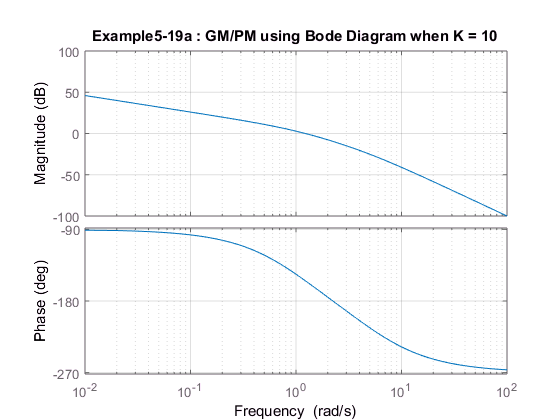

clear all; clc

OL_TF = tf([10], [1 6 5 0]);
figure; bode(OL_TF), grid
title('Example5-19a : GM/PM using Bode Diagram when K = 10')

When K = 10...the system is STABLE

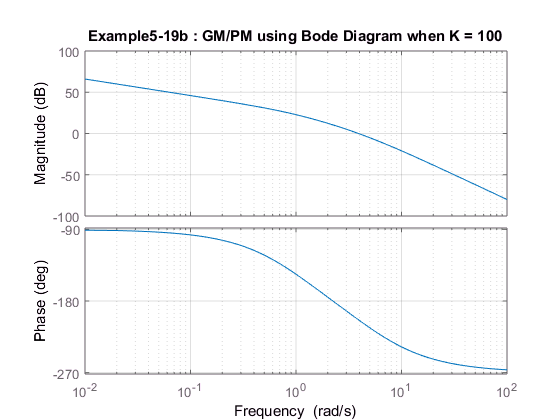

GM_dB = 8;
PM_deg = 21;

OL_TF2 = tf([100], [1 6 5 0]);
figure; bode(OL_TF2), grid
title('Example5-19b : GM/PM using Bode Diagram when K = 100')

When K = 100...the system is UNSTABLE

GM_dB = -12;
PM_deg = -30;

## 5-20 Using MATLAB, determine GM, PM, phase crossover, and gain crossover

Use function : [GM, PM, wcp, wcg] = margin(sys) Closed Loop system 

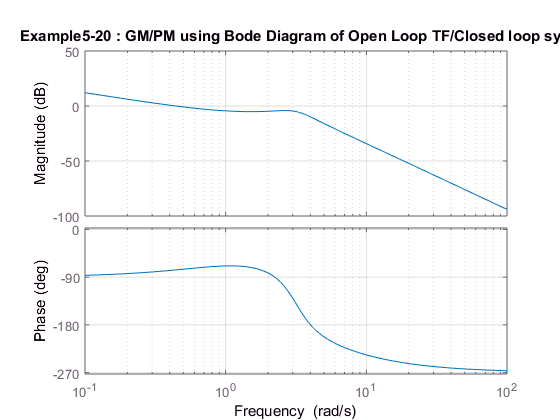

clear all; clc

num = [20 20];
den = conv([ 1 5 0], [1 2 10]);
sys = tf(num, den);
w = logspace(-1, 2, 100);

figure; 
bode(sys, w),grid
title('Example5-20 : GM/PM using Bode Diagram of Open Loop TF/Closed loop sys')

[GM, PM, wcp, wcg] = margin(sys);
GM_dB = 20*log10(GM);
margins = [GM_dB PM, wcp, wcg]

margins =     9.9301  103.6573    4.0132    0.4426


GM & PM > 0, Therefore system is STABLE!

## 5-21 Determine the Resonance Peak/ Resonance Frequency and Bandwidth

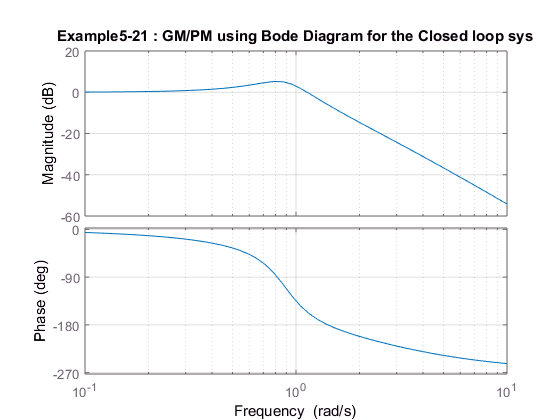

clear all; clc

num = [1];
den = [0.5 1.5 1 0];

Gs = tf(num, den);
sys = feedback(Gs, 1);
w = logspace(-1, 1);

figure; 
bode(sys, w), grid
title('Example5-21 : GM/PM using Bode Diagram for the Closed loop sys')

[mag, ph, w] = bode(sys, w);
[Mp, k] = max(mag);
resonance_peak = 20 * log10(Mp)

resonance_peak = 5.2388

resonance_freq = w(k)

resonance_freq = 0.7906


[~, n] = find( 20*log10(mag) >= -3);
bandwidth = w(length(n)+1)

bandwidth = 1.2649